clearvars; close all; clc;

# Esercitazione 7

### Definitions

A=[0 1;0 -1];
B=[0;1];
C=[1 0];
D=0;

Ts=0.05;

### Discretize and state feedback

sys_x=ss(A,B,eye(2),0);
sys_dt=c2d(ss(A,B,C,D),Ts,'zoh');
[Ad,Bd,Cd,Dd]=ssdata(sys_dt);

### Problem 1

Cy=eye(2);
Cz=eye(2);
Dz=[0;0];
Cc=Cz;
Dc=Dz;

Q=diag([100 1]);
R=1;
cmode=0;
h=Ts;
z_max=[inf inf];
z_min=-[inf inf];
u_max=1;
u_min=-1;
du_max=inf;
du_min=-inf;
Hp=100;
Hu=100;
Hw=1;
z_blk=1;
u_blk=1;

md=MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk,Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h,cmode,'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...



x0=[0.8;0];

#### Simulation

t_sim=6;
out=sim('sim_esercitazione_7');

Update start, t=0.00
Update start, t=0.05
Update start, t=0.10
Update start, t=0.15
Update start, t=0.20
Update start, t=0.25
Update start, t=0.30
Update start, t=0.35
Update start, t=0.40
Update start, t=0.45
Update start, t=0.50
Update start, t=0.55
Update start, t=0.60
Update start, t=0.65
Update start, t=0.70
Update start, t=0.75
Update start, t=0.80
Update start, t=0.85
Update start, t=0.90
Update start, t=0.95
Update start, t=1.00
Update start, t=1.05
Update start, t=1.10
Update start, t=1.15
Update start, t=1.20
Update start, t=1.25
Update start, t=1.30
Update start, t=1.35
Update start, t=1.40
Update start, t=1.45
Update start, t=1.50
Update start, t=1.55
Update start, t=1.60
Update start, t=1.65
Update start, t=1.70
Update start, t=1.75
Update start, t=1.80
Update start, t=1.85
Update start, t=1.90
Update start, t=1.95
Update start, t=2.00
Update start, t=2.05
Update start, t=2.10
Update start, t=2.15
Update start, t=2.20
Update start, t=2.25
Update start, t=2.30
Update start,

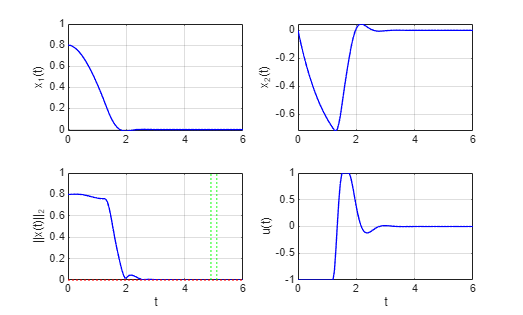

figure(2);
subplot(221), plot(out.x.time,out.x.data(:,1),'b','LineWidth',1.0);
hold on, grid on, ylabel('x_1(t)');
subplot(222), plot(out.x.time,out.x.data(:,2),'b','LineWidth',1.0);
hold on, grid on, ylabel('x_2(t)');

subplot(223), plot(out.x.time,sqrt(out.x.data(:,1).^2+out.x.data(:,2).^2),'b','LineWidth',1.0);
hold on, grid on, ylabel('||x(t)||_2'), xlabel('t'),
yline(0.00001,':r','LineWidth',1.0),
yline(-0.00001,':r','LineWidth',1.0),
xline(5*1.02,':g','LineWidth',1.0),
xline(5*0.98,':g','LineWidth',1.0);

subplot(224), plot(out.u.time,out.u.data,'b','LineWidth',1.0),
hold on, grid on, ylabel('u(t)'), xlabel('t');

### Problem 2

Cy=eye(2);
Cz=eye(2);
Dz=[0;0];
Cc=Cz;
Dc=Dz;

Q=diag([1000 1]);
R=1;
cmode=0;
h=Ts;
z_max=[inf inf];
z_min=-[inf 0];
u_max=1;
u_min=-1;
du_max=inf;
du_min=-inf;
Hp=50;
Hu=50;
Hw=1;
z_blk=1;
u_blk=1;

md2=MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk,Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h,cmode,'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...



x0=[-0.8;0];

#### Simulation

t_sim=3;
out=sim('sim_esercitazione_7');

Update start, t=0.00
Update start, t=0.05
Update start, t=0.10
Update start, t=0.15
Update start, t=0.20
Update start, t=0.25
Update start, t=0.30
Update start, t=0.35
Update start, t=0.40
Update start, t=0.45
Update start, t=0.50
Update start, t=0.55
Update start, t=0.60
Update start, t=0.65
Update start, t=0.70
Update start, t=0.75
Update start, t=0.80
Update start, t=0.85
Update start, t=0.90
Update start, t=0.95
Update start, t=1.00
Update start, t=1.05
Update start, t=1.10
Update start, t=1.15
Update start, t=1.20
Update start, t=1.25
Update start, t=1.30
Update start, t=1.35
Update start, t=1.40
Update start, t=1.45
Update start, t=1.50
Update start, t=1.55
Update start, t=1.60
Update start, t=1.65
Update start, t=1.70
Update start, t=1.75
Update start, t=1.80
Update start, t=1.85
Update start, t=1.90
Update start, t=1.95
Update start, t=2.00
Update start, t=2.05
Update start, t=2.10
Update start, t=2.15
Update start, t=2.20
Update start, t=2.25
Update start, t=2.30
Update start,

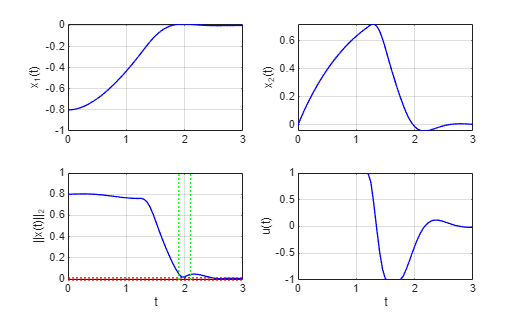


figure(3);
subplot(221), plot(out.x.time,out.x.data(:,1),'b','LineWidth',1.0);
hold on, grid on, ylabel('x_1(t)');
subplot(222), plot(out.x.time,out.x.data(:,2),'b','LineWidth',1.0);
hold on, grid on, ylabel('x_2(t)');

subplot(223), plot(out.x.time,sqrt(out.x.data(:,1).^2+out.x.data(:,2).^2),'b','LineWidth',1.0);
hold on, grid on, ylabel('||x(t)||_2'), xlabel('t'),
yline(0.01,':r','LineWidth',1.0),
yline(-0.01,':r','LineWidth',1.0),
xline(2*1.05,':g','LineWidth',1.0),
xline(2*0.95,':g','LineWidth',1.0);

subplot(224), plot(out.u.time,out.u.data,'b','LineWidth',1.0),
hold on, grid on, ylabel('u(t)'), xlabel('t');